# Actividad1

## Velocidades lineales y angulares.

#### Elazar Olivas Gaspar | A01731405

Para la actividad 1 se propone el siguiente modelo:

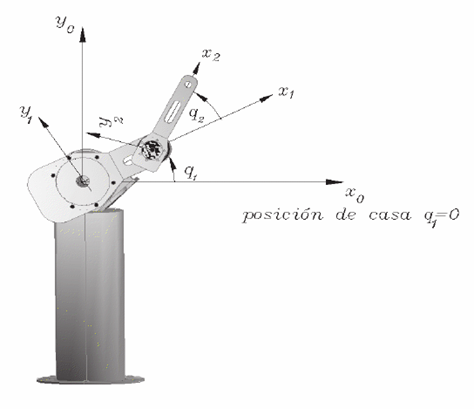

Figura 1: Modelo de brazo robotico con 2 grados de libertad de juntas rotacionales.

Con el fin empezar a entender el modelo se hacen las siguientes observaciones.

- Ambas juntas son rotacionales.

- ambas juntas giran sobre el eje de las z.

Para esto se hace la solución con un código en matlab para el analisis analítico de brazo.

### Solución con código en matlab:

Se empieza por limpiar el área de trabajo, consola y ventanas de matlab.

Esto se hace con el fin de empezar la solución de el problema con un entorno limpio.

clear all;
close all;
clc;

A continuacion se hace la declaracion de variables simbolicas para el calculo analítico de las velocidades.

syms t th1(t) th2(t) l1 l2;

Se declara las varibles:

t->tiempo.

th1->angulo de la primera junta.

th2->angulo de la segunda junta.

l1->largo de primer segmento.

l2->largo del segundo segmento.

Se hace la configuracion del robot.

0 = rotacional.

1 = prismatica.

RP = [0 0];

Se crea un vector con 2 ceros debido a que el modelo es un brazo con 2 juntas rotacionales.

Se crea un vector de cordenadas articulares.

disp('Cordenadas articulares');

Cordenadas articulares


Q = [th1 th2] %Muestra las cordenadas articules

$$Q(t) = \left(\begin{array}{cc} {\mathrm{th}}_{1}\left(t\right) & {\mathrm{th}}_{2}\left(t\right) \end{array}\right)$$

Se crea el vector para las velocidades articulares.

disp('Velocidades articulares');

Velocidades articulares


Qp = diff(Q,t)

$$Qp(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) \end{array}\right)$$

Se establece el grado de libertad del robot.

disp('Grados de libertad');

Grados de libertad


GDL = size(RP,2) %Se obtiene el numero de columans de RP

GDL = 2

GDL_str = num2str(GDL);

#### Articulacion 1

    Matriz de posición de la primera junta.

H = [x,y,z]

disp('Matriz de pocisión de junta 1');

Matriz de pocisión de junta 1


P(:,:,1) = [l1*cos(th1); l1*sin(th1); 0]

$$P = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

Se toma la z como 0, debido que al girar sobre su eje z, no hay cambio en la posición.

    Matriz de rotación.

disp('Matriz de rotación de junta 1');

Matriz de rotación de junta 1


R(:,:,1) = [cos(th1) -sin(th1) 0;
            sin(th1)  cos(th1) 0;
            0         0        1;]

$$R = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

De forma similar a el anterior se puede observar el 1 en la novena posición indicandonos que la junta gira sobre este eje.

#### Articulacion 2

    Matriz de posición para la segunda junta.

disp('Matriz de posición de junta 2');

Matriz de posición de junta 2


P(:,:,2) = [l1*cos(th1)+l2*cos(th1+th2); % x 
            l1*sin(th1)+l2*sin(th1+th2); % y 
            0]                           % z

$$\left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

Como se observa dentro de la posición de la segunda junta se toma encuenta el la posicion de la primera con el fin de obtener la posicion final.

    Matriz de rotación para la segunda junta.

disp('Matriz de rotacion de junta 2');

Matriz de rotacion de junta 2


R(:,:,2) = [cos(th2) -sin(th2) 0;
            sin(th2)  cos(th2) 0;
            0         0        1;]

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Se crea vector de zeros para conformar la matriz homogenea.

disp('Vector de ceros');

Vector de ceros


V_ceros = zeros(1,3)

V_ceros =      0     0     0


#### Matriz de transformacion homogenea.

Se inicializan las matrices de transformacion homogeneas locales.

A(:,:,GDL)=simplify([R(:,:,GDL)   P(:,:,GDL); ...
                    V_ceros  1]);

Se inicializan las matrices de transformacion homogenea globales.

T(:,:,GDL)=simplify([R(:,:,GDL)   P(:,:,GDL); ...
                    V_ceros  1]);

#### Marco de referencia inercial.

P0(:,:,GDL) = P(:,:,GDL);
R0(:,:,GDL) = R(:,:,GDL);

#### Cinematica directa

for i = 1:GDL
    i_str = num2str(i);
    %locales
    disp(strcat('matriz de transformacion locar A',i_str))
    A(:,:,i)=simplify([R(:,:,i)     P(:,:,i); ...
                       V_ceros 1])

    %globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
        %se miltiplica el actual por el anterior gdl
    catch
        T(:,:,i) = A(:,:,i) %caso especifico donde marca error en el try
    end

    disp (strcat('Matriz de transformacion globat T',i_str))
    T(:,:,i)=simplify(T(:,:,i))

    %Obtiene la matriz de rotacion R0 y el vector de translacion de p0
    %de la matriz de transformacion homogenea global T(:,:,GDL)
    R0(:,:,i) = T(1:3,1:3,i)
    P0(:,:,i) = T(1:3,4,i)
    
end

matriz de transformacion locar A1


$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformacion globat T1


$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

matriz de transformacion locar A2


$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformacion globat T2


$$\left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{3} & -\sigma_{2} & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{1}\,\cos\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left(\sigma_{1}\right)\\ \sigma_{2} & \sigma_{3} & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{1}\,\sin\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left(\sigma_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\\ \sigma_{2}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{3}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{1}\,\cos\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left(2\,{\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{1}\,\sin\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left(2\,{\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

#### Calculo de velocidades

Se procede a hacer el calculo de la velocidad lineal y angular de forma analítica.

jv_a(:,GDL)=P0(:,:,GDL);
jw_a(:,GDL)=P0(:,:,GDL);

for k = 1:GDL
    if ((RP(k)==0)|(RP(k)==1))
        %para articulaciones rotacionales
        try 
            jv_a(:,k)=cross(R0(:,3,k-1),P0(:,:,GDL)-P0(:,:,k-1));
            jw_a(:,k)=R0(:,3,k-1);
        catch
            jv_a(:,k)=cross([0,0,1],P0(:,:,GDL)); %matiz de rotacion de 0 respecto 
            %a 0 es la matriz identidad 
            jw_a(:,k)=[0,0,1];%si no hay matriz de rotacion previa 
            %se obtiene la matriz identidad
        end %end try
    else
        %para articulaciones prismaticas
        try
            jv_a(:,k)=R0(:,3:k-1);
        catch
            jv_a(:,k)=[0 0 1];%si no hay matriz de rotacion previa se obtiene la matriz identidad
        end %end try2
            jw_a(:,k) = [0 0 0];%en juntas prismaticas no hat velocidad angular
    
    end %end if

end %end for

Despues de esto se hace el despliegue del jacobiano que se obtivo de forma analítica.

disp('Jacobiano lineal obtenido de forma analitica');

Jacobiano lineal obtenido de forma analitica


jv_a = simplify(jv_a)

$$jv\_a = \begin{array}{l} \left(\begin{array}{cc} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-l_{1}\,\sin\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)-\sigma_{1} & -l_{1}\,\sin\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)-\sigma_{1}\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{1}\,\cos\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{2} & l_{1}\,\cos\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{2}\\ 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(2\,{\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=l_{2}\,\cos\left(2\,{\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

disp('Jacobiano angular obtenido de forma analitica');

Jacobiano angular obtenido de forma analitica


jw_a = simplify(jw_a)

$$jw\_a = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

Con el fin de finalizar el proceso del modelado del brazo se completa multiplicando este jacobiano por las velocidades articulares.

disp('Velocidad lineal obtenida mediante jacobiano lineal');

Velocidad lineal obtenida mediante jacobiano lineal


V = simplify(jv_a*Qp')

$$V(t) = \begin{array}{l} \left(\begin{array}{c} -\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\,\left(\sigma_{2}+l_{2}\,\sin\left(\sigma_{1}\right)\right)-\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\left(l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{2}+l_{2}\,\sin\left(\sigma_{1}\right)\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\,\left(\sigma_{3}+l_{2}\,\cos\left(\sigma_{1}\right)\right)+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\left(l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{3}+l_{2}\,\cos\left(\sigma_{1}\right)\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\\ \sigma_{2}=l_{1}\,\sin\left(2\,{\mathrm{th}}_{1}\left(t\right)\right)\\ \sigma_{3}=l_{1}\,\cos\left(2\,{\mathrm{th}}_{1}\left(t\right)\right) \end{array}$$


disp('Velocidad angular obtenida mediante el jacobiano angular');

Velocidad angular obtenida mediante el jacobiano angular


W=simplify(jw_a*Qp')

$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)} \end{array}\right)$$

Al obtener los resultados podemos concluir lo siguiente.


$$W\left(t\right)=\left(\begin{array}{c}
0\\
0\\
\bar{\frac{\partial }{\partial t}\mathrm{\ }{\mathrm{th}}_1 \left(t\right)} +\bar{\frac{\partial }{\partial t}\mathrm{\ }{\mathrm{th}}_2 \left(t\right)} 
\end{array}\right)$$


Para la velocidad angular se puede ver que no hay velocidad en x ni en y, lo cuál es el resultado que se esta esperando debido a que ambas juntas giran sobre z, por lo que no deberiamos de tener nada en las velocidades angulares de x & y. Por otro lado podemos ver que la velocidad angular toma en cuenta ambos angulos sobre los cuales se esta girando.


$$\begin{array}{l}
\;V\left(t\right)\left(\begin{array}{c}
-\bar{\frac{\partial }{\partial t}\mathrm{\ }{\mathrm{th}}_2 \left(t\right)} \,{\left(\sigma_2 +l_2 \,\sin \left(\sigma_1 \right)\right)}-\bar{\frac{\partial }{\partial t}\mathrm{\ }{\mathrm{th}}_1 \left(t\right)} \,{\left(l_1 \,\sin \left({\mathrm{th}}_1 \left(t\right)\right)+\sigma_2 +l_2 \,\sin \left(\sigma_1 \right)\right)}\\
\bar{\frac{\partial }{\partial t}\mathrm{\ }{\mathrm{th}}_2 \left(t\right)} \,{\left(\sigma_3 +l_2 \,\cos \left(\sigma_1 \right)\right)}+\bar{\frac{\partial }{\partial t}\mathrm{\ }{\mathrm{th}}_1 \left(t\right)} \,{\left(l_1 \,\cos \left({\mathrm{th}}_1 \left(t\right)\right)+\sigma_3 +l_2 \,\cos \left(\sigma_1 \right)\right)}\\
0
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_1 =2\,{\mathrm{th}}_1 \left(t\right)+{\mathrm{th}}_2 \left(t\right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_2 =l_1 \,\sin \left(2\,{\mathrm{th}}_1 \left(t\right)\right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_3 =l_1 \,\cos \left(2\,{\mathrm{th}}_1 \left(t\right)\right)
\end{array}$$


En los resultados de la velocidad lineal podemos ver resultados opuestos a los de la velocidad angular, esto es debi a que el modelo gira sobre el eje de las z, por lo que no se podra mover a lo largo de esta, es por esto que podemos ver un cambio en x y en y pero no en z.

Es por estos resultados que se puede saber que se obtuvieron los resultados esperados, debido a que los resultados anteriormente desglozado haces referencia, o son representativos del brazo que se esta modelando. (Figura1)